# **RT-QIBC analysis**

**FarRed1: IF stain**

**FarRed2: EdU incorporation**

**YFP2: IF Cdt1**

**POI(:,3): CRL4Cdt2 activation**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'no dox-gH2AX-DMSO',2:3,3,1:4,[0 0 0],'DMSO','gH2AX','DMSO'; %1      
        'no dox-pCHK1-DMSO',4:5,3,1:4,[0 0 0],'DMSO','pCHK1','DMSO'; %1    
        'no dox-pCHK2-DMSO',6:7,3,1:4,[0 0 0],'DMSO','pCHK2','DMSO'; %1
        
        'dox-gH2AX-DMSO',2:3,4:5,1:4,[0 0 0],'Dox','gH2AX','DMSO'; %1      
        'dox-pCHK1-DMSO',4:5,4:5,1:4,[0 0 0],'Dox','pCHK1','DMSO'; %1    
        'dox-pCHK2-DMSO',6:7,4:5,1:4,[0 0 0],'Dox','pCHK2','DMSO'; %1   
        
        'dox-gH2AX-ATRi',2:3,6:7,1:4,[0 0 0],'Dox','gH2AX','ATRi'; %1      
        'dox-pCHK1-ATRi',4:5,6:7,1:4,[0 0 0],'Dox','pCHK1','ATRi'; %1    
        'dox-pCHK2-ATRi',6:7,6:7,1:4,[0 0 0],'Dox','pCHK2','ATRi'; %1      
        
        'dox-gH2AX-Wee1i',2:3,8:9,1:4,[0 0 0],'Dox','gH2AX','Wee1i'; %1      
        'dox-pCHK1-Wee1i',4:5,8:9,1:4,[0 0 0],'Dox','pCHK1','Wee1i'; %1    
        'dox-pCHK2-Wee1i',6:7,8:9,1:4,[0 0 0],'Dox','pCHK2','Wee1i'; %1
        
        'dox-gH2AX-Aphi',2:3,10,1:4,[0 0 0],'Dox','gH2AX','Aphi'; %1      
        'dox-pCHK1-Aphi',4:5,10,1:4,[0 0 0],'Dox','pCHK1','Aphi'; %1    
        'dox-pCHK2-Aphi',6:7,10,1:4,[0 0 0],'Dox','pCHK2','Aphi'; %1
        
        'dox-gH2AX-HU',2:3,11,1:4,[0 0 0],'Dox','gH2AX','HU'; %1      
        'dox-pCHK1-HU',4:5,11,1:4,[0 0 0],'Dox','pCHK1','HU'; %1    
        'dox-pCHK2-HU',6:7,11,1:4,[0 0 0],'Dox','pCHK2','HU'; %1  
    };


load([dataDir filesep 'C212_data.mat'],'S');

% S = loadData(conditions, dataDir);

framesPerHr = 60/12;
frameDrugAdded = 74;
frameEdU = 0;
timeStart = .6;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

POI_time = arrayfun(@(x) (numFrames - x.POI)/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

**Set Thresholds**

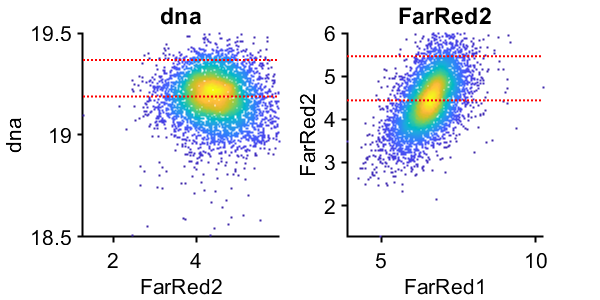

%% Set gates G1
cond=1;
gate = struct();
gates = {'dna','FarRed2'};
plotting = {'FarRed2','FarRed1'};
prctiles = {[50 95], [50 95],[50 95],[50 95],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = isnan(S(cond).POI(:,2)) & isnan(S(cond).POI(:,3)) & ...
        S(cond).dna < 2^19.5 & S(cond).dna > 2^18.5 & S(cond).FarRed2 < 2^6;
    
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(real(log2(xdata)),real(log2(ydata)));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

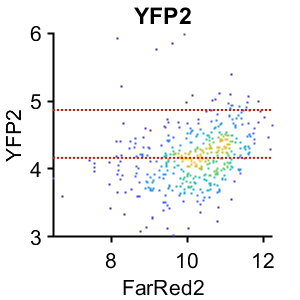


gates = {'YFP2'};
plotting = {'FarRed2'};
prctiles = {[50 95]};
figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 3 & S(cond).POI_time(:,3) > 2 & S(cond).FarRed2 > 2^6 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

**Plot Cdt1 histograms to look at induction**

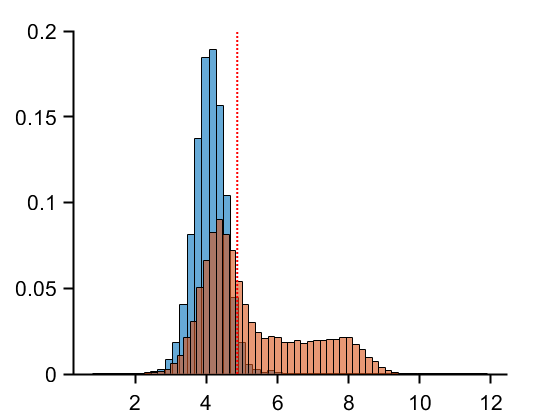

conds=[1 4];
figure, hold on
for i=1:length(conds)
    condition = conds(i);
    histogram(real(log2(S(condition).YFP2)),50,'Normalization','Probability');
end
vline(log2(gate.YFP2_S(2)))

**Dose response EdU Cdt1 (pooled all stains) top and bot fixed, bootstrapped 10k times single plot**

conds=[ 4 7 10];
poiAligned=3;
offset=0;

range = 4:.5:9;
timeGate = [ 2 3];
midpoints = range + (range(2) -range(1))/2;
thresh = gate.FarRed2_G1(2) - gate.FarRed2_G1(1);
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);

cols = lines(3);
outcoeff = [];
for i=1:length(conds)

    ind=~isnan(S(conds(i)).POI(:,poiAligned));
    
    tdata=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    gatedata=log2(S(conds(i)).YFP2(ind));
    ydata=(S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    wells = string(num2str(S(conds(i)).wellindex(:,1:2)));
    
    %%% add next stain
    tdata=[tdata; (numFrames-(S(conds(i)+1).POI(ind,poiAligned)-offset))/framesPerHr];
    gatedata=[gatedata; log2(S(conds(i)+1).YFP2(ind))];
    ydata=[ydata; (S(conds(i)+1).FarRed2(ind) - gate.FarRed2_G1(1))] ;
    wells = [wells; string(num2str(S(conds(i)+1).wellindex(:,1:2)))];
    
    %%% add next stain
    tdata=[tdata; (numFrames-(S(conds(i)+2).POI(ind,poiAligned)-offset))/framesPerHr];
    gatedata=[gatedata; log2(S(conds(i)+2).YFP2(ind))];
    ydata=[ydata; (S(conds(i)+2).FarRed2(ind) - gate.FarRed2_G1(1))] ;
    wells = [wells; string(num2str(S(conds(i)+2).wellindex(:,1:2)))];
    
    
    inds = tdata >= timeGate(1) & tdata <= timeGate(2) & gatedata > log2(gate.YFP2_S(1));
    tdata = tdata(inds);
    ydata = ydata(inds);
    gatedata = gatedata(inds);
    wells = wells(inds);


    %%%%% get fit stuff
    ind= gatedata < log2(gate.YFP2_S(2)) & gatedata > log2(gate.YFP2_S(1));
    top_edu = nanmean(ydata(ind));
    ydata = ydata/top_edu;
    top_edu = nanmean(ydata(ind));
    
    ind= gatedata > 7 &  gatedata < 8 & ydata < 1000;
    bot_edu = nanmean(ydata(ind));
    
    [binData, edges] = bin_xy(gatedata, ydata, {'mean','median'},...
        'Edges',range,'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
    edges = edges(1:end-1);
    midpoints = edges + (edges(2) -edges(1))/2;
    
    %% Get fit
    minResponse=prctile(binData.g_ydata,5);
    midResponse=median(midpoints(binData.xInd));
    minDose=min(midpoints(binData.xInd));
    maxDose=max(midpoints(binData.xInd));
    
    sigmoid=@(beta,x)top_edu-(top_edu-bot_edu)./(1+(2.^(beta(1) - x)).^beta(2));
    coeffs = fitSigmoid(gatedata,ydata,sigmoid,[ midResponse 1]);
    coeffBoot = bootstrp(1000,@(x,y) fitSigmoid(x,y,sigmoid,[ midResponse 1]), gatedata,ydata,'Options',statset('UseParallel',true));
    coeffFilt = coeffBoot(coeffBoot(:,1) > 0,:);
    suppression_theory = top_edu/bot_edu;
    fprintf('Cond %d, suppression fit: %f',i,suppression_theory)
    suppression_max= top_edu/sigmoid(coeffs,maxDose);
    fprintf('Cond %d, suppression fit: %f',i,suppression_max)
    coeffs
%         suppression_boot = top_edu./coeffFilt(:,1);
%         supp_int = prctile(suppression_boot,[2.5 97.5])
    mid_ind = prctile(coeffFilt,[2.5,97.5])
    outcoeff(:,i) = coeffFilt(:,1);
    
    %% Plot

    hold on
    errorbar(midpoints, binData.mean(:), 2*binData.sem(:),'o','LineWidth',1.5,'MarkerSize',5,'Color',cols(i,:),'MarkerFaceColor','w')
    
    xpoints = linspace(min(gatedata),max(midpoints),1000);
    a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
    plot([coeffs(1) coeffs(1)],[0 (sigmoid(coeffs,coeffs(1)))] ,':','Color',cols(i,:),'LineWidth',2)
    scatter(coeffs(1),(sigmoid(coeffs,coeffs(1))),50,'o','MarkerEdgeColor',[0 0 0],'LineWidth',1.5)
    
    xlabel('log2[ND-Cdt1 (RFU)]');
    ylabel('EdU (RFU)');
    xlim([4 9])
    xticks([4:1:9])
    ylim([0 1.2])
    vline(log2(gate.YFP2_S),'k');
    %     h=hline(thresh,'k--');
    set(gca,'FontSize',16, 'LineWidth',1.5)
    axis square
%         figure
%         dscatter(gatedata,ydata)
%         xlim([4 10])
cells = binData.numCells
total_cells = length(gatedata)

end

Cond 1, suppression fit: 25.696955

Cond 1, suppression fit: 25.696576

coeffs =     5.4896    6.3408


mid_ind =     5.3759    4.7131
    5.6022    9.9036


cells =    213   277   122    92    71    80    88    79    63    22


total_cells = 1110

Cond 2, suppression fit: 17.572316

Cond 2, suppression fit: 17.571817

coeffs =     5.3704    5.6677


mid_ind =     5.2705    4.3661
    5.4703    8.0758


cells =    178   168    92    59    61    52    44    55    48    12


total_cells = 770

Cond 3, suppression fit: 17.038585

Cond 3, suppression fit: 17.037152

coeffs =     5.3275    5.1251


mid_ind =     5.2199    4.0147
    5.4442    6.6941


cells =    236   201    94    70    85    72    81    62    45    13


total_cells = 961

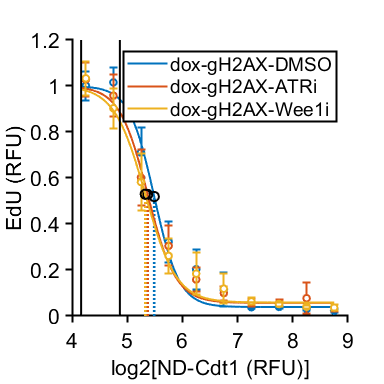

legend(a,conditions(conds, 1),'location','northeast');
% legend('boxoff')
print_pdf([pwd() '\Figs\edu_dose_response_drugs_all.pdf'])


diff1 = prctile(outcoeff(:,1) - outcoeff(:,2),[2.5,97.5])

diff1 =    -0.0395    0.2733


diff2 = prctile(outcoeff(:,1) - outcoeff(:,3),[2.5,97.5])

diff2 =    -0.0068    0.3178


**EdU**

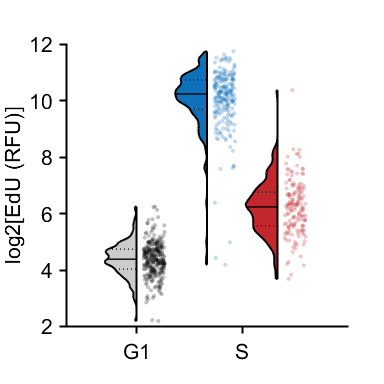

gatedata = {};
poiAligned = 3;
offset = 0;
rng(1)
% DMSO Non expressing 1-2 hrs
cond = 4;
xdata=(numFrames-(S(cond).POI(:,poiAligned)-offset))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 2 & xdata > 1;
gatedata{2} = log2(ydata3(ind));

% DMSO Expressing 1-2 hrs
ind = ydata2 > 2^6 & xdata < 2 & xdata > 1;
gatedata{3} = log2(ydata3(ind));

% DMSO g1 cells
ind = ydata2 < gate.YFP2_S(2) & ydata3 < 2*gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{1} = log2(ydata3(ind));



ally = cell2mat(gatedata');
groups = vertcat(1*ones(size(gatedata{1})), 2*ones(size(gatedata{2})), 3*ones(size(gatedata{3})));
figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames', {'G1','ND-Cdt1 -','ND-Cdt1 + '});
set(h{1},'EdgeColor',[0 0 0 ],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [ 0 0 0; cols([1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 10,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[EdU (RFU)]')
xticks([1 2.5])
xticklabels({'G1','S'})
% ylim([0 2.25])
% xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\edu_compare'])

**gH2AX alt**

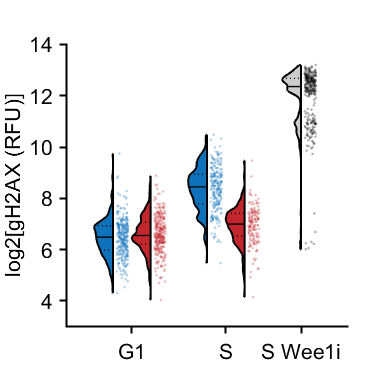

gatedata = {};
poiAligned = 3;
rng(1)
% DMSO Non expressing 1-2 hrs
cond = 4;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 2 & xdata > 1;
gatedata{3} = log2(ydata1(ind));

% DMSO Expressing 1-2 hrs
ind = ydata2 > 2^6 & xdata < 2 & xdata > 1;
gatedata{4} = log2(ydata1(ind));

% DMSO g1 cells
ind = ydata2 < gate.YFP2_S(2) & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{1} = log2(ydata1(ind));

% DMSO g1 cells expression
ind = ydata2 > 2^6 & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{2} = log2(ydata1(ind));

% Wee1i not expressing, 5-6 hrs
cond = 10;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 6 & xdata > 5;
ind = randsample(find(ind),300);
gatedata{5} = log2(ydata1(ind));

ally = cell2mat(gatedata');
groups = vertcat(1*ones(size(gatedata{1})), 2*ones(size(gatedata{2})), ...
    3*ones(size(gatedata{3})), 4*ones(size(gatedata{4})), 5*ones(size(gatedata{5})));
group_list = 1:max(groups);
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames', {'G1','G1 ND','ND-Cdt1 -','ND-Cdt1 + ','Wee1i -'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0 ],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [cols([1 2 1 2 ],:); [0 0 0]];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:),[.8 .8 .8]}')
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(xkey(groups)'+jit, (ally), 4,groupcol(groups,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[gH2AX (RFU)]')
xticks([xkey(1:2:length(xkey)-1)+.5 6])
xticklabels({'G1','S','S Wee1i'})
ylim([3 14])
axis square
% xtickangle(45)
print_pdf([pwd() '\Figs\gh2ax_compare_alt'])

**pCHK1**

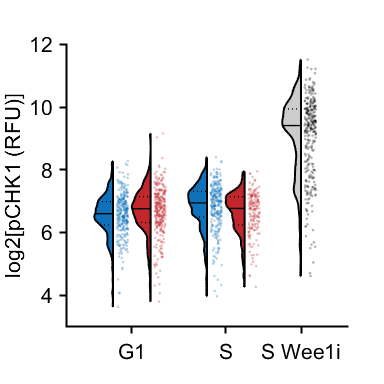

gatedata = {};
poiAligned = 3;
rng(1)
% DMSO Non expressing 1-2 hrs
cond = 5;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 2 & xdata > 1;
gatedata{3} = log2(ydata1(ind));

% DMSO Expressing 1-2 hrs
ind = ydata2 > 2^6 & xdata < 2 & xdata > 1;
gatedata{4} = log2(ydata1(ind));

% DMSO g1 cells
ind = ydata2 < gate.YFP2_S(2) & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{1} = log2(ydata1(ind));

% DMSO g1 cells expression
ind = ydata2 > 2^6 & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{2} = log2(ydata1(ind));

% Wee1i not expressing, 5-6 hrs
cond = 11;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 6 & xdata > 5;
ind = randsample(find(ind),300);
gatedata{5} = log2(ydata1(ind));


ally = cell2mat(gatedata');
groups = vertcat(1*ones(size(gatedata{1})), 2*ones(size(gatedata{2})), ...
    3*ones(size(gatedata{3})), 4*ones(size(gatedata{4})), 5*ones(size(gatedata{5})));
group_list = 1:max(groups);
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames', {'G1','G1 ND','ND-Cdt1 -','ND-Cdt1 + ','Wee1i -'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0 ],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [cols([1 2 1 2 ],:); [0 0 0]];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:),[.8 .8 .8]}')
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(xkey(groups)'+jit, (ally), 4,groupcol(groups,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[pCHK1 (RFU)]')
xticks([xkey(1:2:length(xkey)-1)+.5 6])
xticklabels({'G1','S','S Wee1i'})
ylim([3 12])
axis square
% xtickangle(45)
print_pdf([pwd() '\Figs\pCHK1_compare_alt'])

**pCHK2**

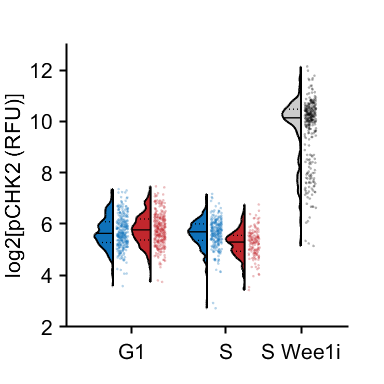

gatedata = {};
poiAligned = 3;
rng(2)
% DMSO Non expressing 1-2 hrs
cond = 6;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 2 & xdata > 1;
gatedata{3} = log2(ydata1(ind));

% DMSO Expressing 1-2 hrs
ind = ydata2 > 2^6 & xdata < 2 & xdata > 1;
gatedata{4} = log2(ydata1(ind));

% DMSO g1 cells
ind = ydata2 < gate.YFP2_S(2) & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{1} = log2(ydata1(ind));

% DMSO g1 cells expression
ind = ydata2 > 2^6 & ydata3 < gate.FarRed2_G1(2) & S(cond).dna < 2^19.5;
ind = randsample(find(ind),300);
gatedata{2} = log2(ydata1(ind));

% Wee1i not expressing, 5-6 hrs
cond = 12;
xdata=(numFrames-(S(cond).POI(:,poiAligned)))/framesPerHr;
ydata1=(S(cond).FarRed1(:,end));
ydata2=(S(cond).YFP2(:));
ydata3=(S(cond).FarRed2(:));

ind = ydata2 < gate.YFP2_S(2) & xdata < 6 & xdata > 5;
ind = randsample(find(ind),300);
gatedata{5} = log2(ydata1(ind));


ally = cell2mat(gatedata');
groups = vertcat(1*ones(size(gatedata{1})), 2*ones(size(gatedata{2})), ...
    3*ones(size(gatedata{3})), 4*ones(size(gatedata{4})), 5*ones(size(gatedata{5})));
group_list = 1:max(groups);
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames', {'G1','G1 ND','ND-Cdt1 -','ND-Cdt1 + ','Wee1i -'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0 ],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [cols([1 2 1 2 ],:); [0 0 0]];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:),[.8 .8 .8]}')
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(xkey(groups)'+jit, (ally), 4,groupcol(groups,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[pCHK2 (RFU)]')
xticks([xkey(1:2:length(xkey)-1)+.5 6])
xticklabels({'G1','S','S Wee1i'})
ylim([2 13])
axis square
% xtickangle(45)
print_pdf([pwd() '\Figs\pCHK2_compare_alt'])

function coeffs = fitSigmoid(dose, response, func, init)
opts = statset('nlinfit');
% opts.RobustWgtFun = 'bisquare';
opts.ErrorModel = 'proportional';
coeffs = nlinfit(dose,response,func,init,opts);
end
